# Spatial and Frequency Feature Extraction

## About the Data

We will be extracting the necessary features from 9 different class of Birds. The classes available to us are:-

- `Baltimore Oriole` $\to$` Class 0`

- `Cockatoos` $\to$` Class 1`

- `Cotinga` $\to$` Class 2`

- `Crow` $\to$` Class 3`

- `Macaw` $\to$` Class 4`

- `Northern`` Cardinal `$\to$` Class 5`

- `Parakeet` $\to$` Class 6`

- `Parrot` $\to$` Class 7`

- `Toucan` $\to$` Class 8`

## Features to be Extracted

We will be extracting the following features for the **Spatial Domain**:

- `Mean` $\to$` For Red, Green, Blue and Gray`

- `Median` $\to$` For Red, Green, Blue and Gray`

- `Standard Deviation`

- `Maximum`

- `Minimum`

- `Inter Quartile Range (IQR)`

- `Skewness`

- `Kurtosis`

- `Entropy`

As for the **Frequency Domain**, we will focus on:

- `Average`

- `Median `

- `Maximum`

- `Minimum`

These will be preformed after applying both the `Fast Fourier Transformation` and `Haar Wavelet Transformation` on Red channel. Apart from the above mentioned features we will also extract the `Discrete Cosine Transformation` of the image for the Frequency Domain.

## **Feature Extraction Procedure**

### `Baltimore Oriole (Class 0)`

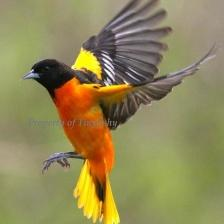

mydir='D:\USER\Desktop\PYTHON CLASS\Bird Classification\Birds\Baltimore_Oriole';
fileformat='*.jpg';
dd=dir(fullfile(mydir,fileformat));
assert(numel(dd) > 0, 'No file was found. Check that the path is correct');
my_img = struct('img', cell(size(dd)));
k=numel(dd)+1;
for zz=1:numel(dd)
my_img(zz).img = imread(fullfile(mydir,dd(zz).name));
end


for i= 1:numel(dd)
    current = imresize(my_img(i).img,[400,400]);
    
%%% Spatial Domain
 % RGB Channels
    % Red image
    RedMean = mean(mean(current(:,:,1))); 
    RedMedian = median(median(current(:,:,1)));
    % Green image
    GreenMean = mean(mean(current(:,:,2))); 
    GreenMedian = median(median(current(:,:,2))); 
    % Blue image
    BlueMean = mean(mean(current(:,:,3))); 
    BlueMedian = median(median(current(:,:,3)));

    % Gray Scale Image
    GrayImage = double(rgb2gray(current));

    % Statistical Measures
    Mean = mean(mean(GrayImage)); 
    Median = median(median(GrayImage));
    Maximum = max(max(GrayImage));
    Minimum = min(min(GrayImage));
    Std_Dev = std(std(double(GrayImage)));
    Kurtosis = real(kurtosis(GrayImage,1,'all'));
    Skewness = real(skewness(GrayImage,1,'all'));
    IQR = iqr(GrayImage,'all');

    % Entropy -> Statistical measure of randomness that can be used to characterize the texture of input image.
    Entropy = entropy(GrayImage); 
    
%%% Frequency Domain
    % Fast-Fourier Transform of Red Channels
    Red_FFT = fft2(current(:,:,1));
    
    FFT_Mean = real(mean(mean(Red_FFT)));
    FFT_Median = real(median(median(Red_FFT)));
    FFT_Maximum = real(max(max(Red_FFT)));
    FFT_Minimum = real(min(min(Red_FFT)));

    % Haar Wavelet Transformation of Red Channels
    Red_Wave = wave(current(:,:,1),'haar',3); 

    Wave_Mean = real(mean(mean(Red_Wave)));
    Wave_Median = real(median(median(Red_Wave)));
    Wave_Maximum = real(max(max(Red_Wave)));
    Wave_Minimum = real(min(min(Red_Wave)));


    % Discrete Cosine Transformation
    DCT_Img = dct2(current(:,:,1)); 
    DCT = DCT_Img(1,1);


    % Selected Column Values
    Column_Names = [RedMean, RedMedian, GreenMean, GreenMedian, BlueMean, BlueMedian, Mean, Median, Maximum, Minimum, Std_Dev, Kurtosis, Skewness, IQR, Entropy, FFT_Mean, FFT_Median, FFT_Maximum, FFT_Minimum, Wave_Mean, Wave_Median, Wave_Maximum, Wave_Minimum, DCT];
    % Writing into Excel Sheets
    writematrix(Column_Names,'D:\USER\Desktop\PYTHON CLASS\Bird Classification\Birds\Class0.csv','WriteMode', 'append');
end

### `Cockatoos (Class 1)`

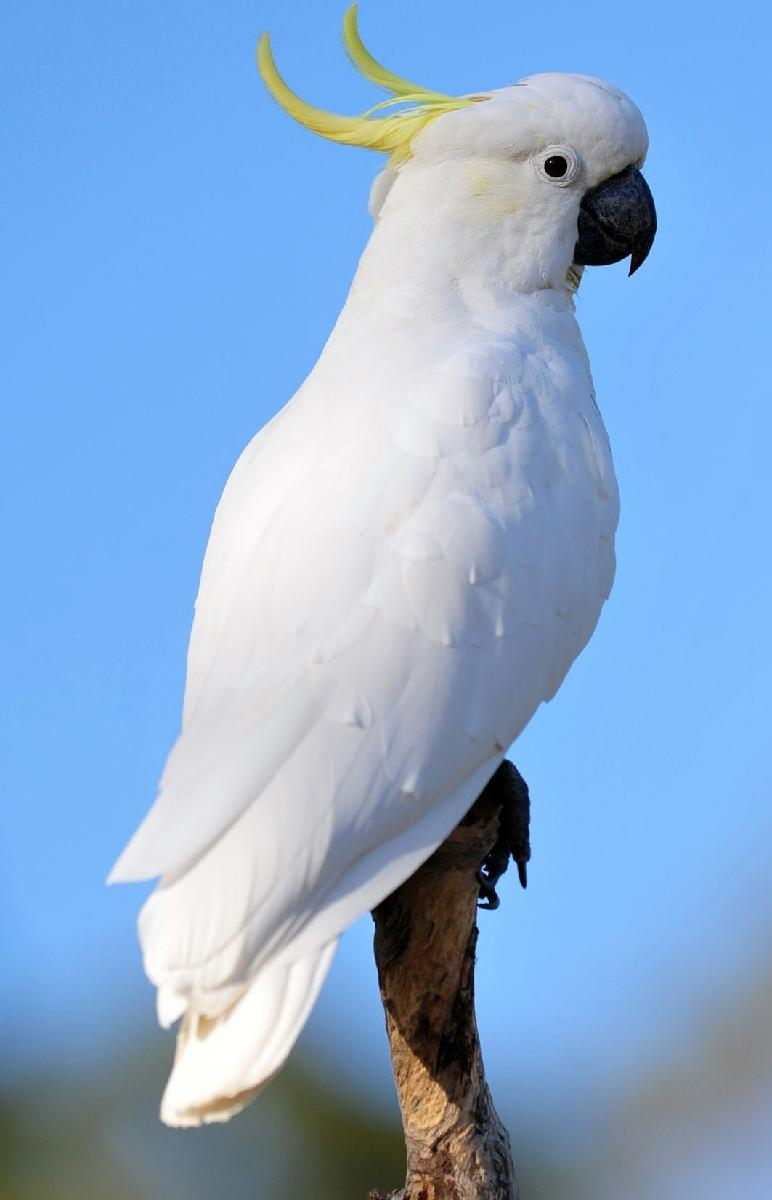

mydir='D:\USER\Desktop\PYTHON CLASS\Bird Classification\Birds\Cockatoos';
fileformat='*.jpg';
dd=dir(fullfile(mydir,fileformat));
assert(numel(dd) > 0, 'No file was found. Check that the path is correct');
my_img = struct('img', cell(size(dd)));
k=numel(dd)+1;
for zz=1:numel(dd)
my_img(zz).img = imread(fullfile(mydir,dd(zz).name));
end


for i= 1:numel(dd)
    current = imresize(my_img(i).img,[400,400]);
    
%%% Spatial Domain
 % RGB Channels
    % Red image
    RedMean = mean(mean(current(:,:,1))); 
    RedMedian = median(median(current(:,:,1)));
    % Green image
    GreenMean = mean(mean(current(:,:,2))); 
    GreenMedian = median(median(current(:,:,2))); 
    % Blue image
    BlueMean = mean(mean(current(:,:,3))); 
    BlueMedian = median(median(current(:,:,3)));

    % Gray Scale Image
    GrayImage = double(rgb2gray(current));

    % Statistical Measures
    Mean = mean(mean(GrayImage)); 
    Median = median(median(GrayImage));
    Maximum = max(max(GrayImage));
    Minimum = min(min(GrayImage));
    Std_Dev = std(std(double(GrayImage)));
    Kurtosis = real(kurtosis(GrayImage,1,'all'));
    Skewness = real(skewness(GrayImage,1,'all'));
    IQR = iqr(GrayImage,'all');

    % Entropy -> Statistical measure of randomness that can be used to characterize the texture of input image.
    Entropy = entropy(GrayImage); 
    
%%% Frequency Domain
    % Fast-Fourier Transform of Red Channels
    Red_FFT = fft2(current(:,:,1));
    
    FFT_Mean = real(mean(mean(Red_FFT)));
    FFT_Median = real(median(median(Red_FFT)));
    FFT_Maximum = real(max(max(Red_FFT)));
    FFT_Minimum = real(min(min(Red_FFT)));

    % Haar Wavelet Transformation of Red Channels
    Red_Wave = wave(current(:,:,1),'haar',3); 

    Wave_Mean = real(mean(mean(Red_Wave)));
    Wave_Median = real(median(median(Red_Wave)));
    Wave_Maximum = real(max(max(Red_Wave)));
    Wave_Minimum = real(min(min(Red_Wave)));


    % Discrete Cosine Transformation
    DCT_Img = dct2(current(:,:,1)); 
    DCT = DCT_Img(1,1);


    % Selected Column Values
    Column_Names = [RedMean, RedMedian, GreenMean, GreenMedian, BlueMean, BlueMedian, Mean, Median, Maximum, Minimum, Std_Dev, Kurtosis, Skewness, IQR, Entropy, FFT_Mean, FFT_Median, FFT_Maximum, FFT_Minimum, Wave_Mean, Wave_Median, Wave_Maximum, Wave_Minimum, DCT];
    % Writing into Excel Sheets
    writematrix(Column_Names,'D:\USER\Desktop\PYTHON CLASS\Bird Classification\Birds\Class1.csv','WriteMode', 'append');
end

### `Cotinga (Class 2)`

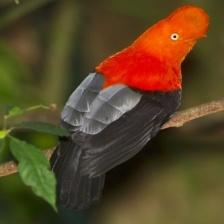

mydir='D:\USER\Desktop\PYTHON CLASS\Bird Classification\Birds\Cotinga';
fileformat='*.jpg';
dd=dir(fullfile(mydir,fileformat));
assert(numel(dd) > 0, 'No file was found. Check that the path is correct');
my_img = struct('img', cell(size(dd)));
k=numel(dd)+1;
for zz=1:numel(dd)
my_img(zz).img = imread(fullfile(mydir,dd(zz).name));
end


for i= 1:numel(dd)
    current = imresize(my_img(i).img,[400,400]);
    
%%% Spatial Domain
 % RGB Channels
    % Red image
    RedMean = mean(mean(current(:,:,1))); 
    RedMedian = median(median(current(:,:,1)));
    % Green image
    GreenMean = mean(mean(current(:,:,2))); 
    GreenMedian = median(median(current(:,:,2))); 
    % Blue image
    BlueMean = mean(mean(current(:,:,3))); 
    BlueMedian = median(median(current(:,:,3)));

    % Gray Scale Image
    GrayImage = double(rgb2gray(current));

    % Statistical Measures
    Mean = mean(mean(GrayImage)); 
    Median = median(median(GrayImage));
    Maximum = max(max(GrayImage));
    Minimum = min(min(GrayImage));
    Std_Dev = std(std(double(GrayImage)));
    Kurtosis = real(kurtosis(GrayImage,1,'all'));
    Skewness = real(skewness(GrayImage,1,'all'));
    IQR = iqr(GrayImage,'all');

    % Entropy -> Statistical measure of randomness that can be used to characterize the texture of input image.
    Entropy = entropy(GrayImage); 
    
%%% Frequency Domain
    % Fast-Fourier Transform of Red Channels
    Red_FFT = fft2(current(:,:,1));
    
    FFT_Mean = real(mean(mean(Red_FFT)));
    FFT_Median = real(median(median(Red_FFT)));
    FFT_Maximum = real(max(max(Red_FFT)));
    FFT_Minimum = real(min(min(Red_FFT)));

    % Haar Wavelet Transformation of Red Channels
    Red_Wave = wave(current(:,:,1),'haar',3); 

    Wave_Mean = real(mean(mean(Red_Wave)));
    Wave_Median = real(median(median(Red_Wave)));
    Wave_Maximum = real(max(max(Red_Wave)));
    Wave_Minimum = real(min(min(Red_Wave)));


    % Discrete Cosine Transformation
    DCT_Img = dct2(current(:,:,1)); 
    DCT = DCT_Img(1,1);


    % Selected Column Values
    Column_Names = [RedMean, RedMedian, GreenMean, GreenMedian, BlueMean, BlueMedian, Mean, Median, Maximum, Minimum, Std_Dev, Kurtosis, Skewness, IQR, Entropy, FFT_Mean, FFT_Median, FFT_Maximum, FFT_Minimum, Wave_Mean, Wave_Median, Wave_Maximum, Wave_Minimum, DCT];
    % Writing into Excel Sheets
    writematrix(Column_Names,'D:\USER\Desktop\PYTHON CLASS\Bird Classification\Birds\Class2.csv','WriteMode', 'append');
end

### `Crow (Class 3)`

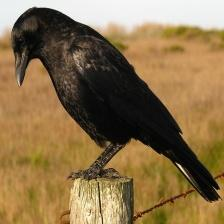

mydir='D:\USER\Desktop\PYTHON CLASS\Bird Classification\Birds\Crow';
fileformat='*.jpg';
dd=dir(fullfile(mydir,fileformat));
assert(numel(dd) > 0, 'No file was found. Check that the path is correct');
my_img = struct('img', cell(size(dd)));
k=numel(dd)+1;
for zz=1:numel(dd)
my_img(zz).img = imread(fullfile(mydir,dd(zz).name));
end


for i= 1:numel(dd)
    current = imresize(my_img(i).img,[400,400]);
    
%%% Spatial Domain
 % RGB Channels
    % Red image
    RedMean = mean(mean(current(:,:,1))); 
    RedMedian = median(median(current(:,:,1)));
    % Green image
    GreenMean = mean(mean(current(:,:,2))); 
    GreenMedian = median(median(current(:,:,2))); 
    % Blue image
    BlueMean = mean(mean(current(:,:,3))); 
    BlueMedian = median(median(current(:,:,3)));

    % Gray Scale Image
    GrayImage = double(rgb2gray(current));

    % Statistical Measures
    Mean = mean(mean(GrayImage)); 
    Median = median(median(GrayImage));
    Maximum = max(max(GrayImage));
    Minimum = min(min(GrayImage));
    Std_Dev = std(std(double(GrayImage)));
    Kurtosis = real(kurtosis(GrayImage,1,'all'));
    Skewness = real(skewness(GrayImage,1,'all'));
    IQR = iqr(GrayImage,'all');

    % Entropy -> Statistical measure of randomness that can be used to characterize the texture of input image.
    Entropy = entropy(GrayImage); 
    
%%% Frequency Domain
    % Fast-Fourier Transform of Red Channels
    Red_FFT = fft2(current(:,:,1));
    
    FFT_Mean = real(mean(mean(Red_FFT)));
    FFT_Median = real(median(median(Red_FFT)));
    FFT_Maximum = real(max(max(Red_FFT)));
    FFT_Minimum = real(min(min(Red_FFT)));

    % Haar Wavelet Transformation of Red Channels
    Red_Wave = wave(current(:,:,1),'haar',3); 

    Wave_Mean = real(mean(mean(Red_Wave)));
    Wave_Median = real(median(median(Red_Wave)));
    Wave_Maximum = real(max(max(Red_Wave)));
    Wave_Minimum = real(min(min(Red_Wave)));


    % Discrete Cosine Transformation
    DCT_Img = dct2(current(:,:,1)); 
    DCT = DCT_Img(1,1);


    % Selected Column Values
    Column_Names = [RedMean, RedMedian, GreenMean, GreenMedian, BlueMean, BlueMedian, Mean, Median, Maximum, Minimum, Std_Dev, Kurtosis, Skewness, IQR, Entropy, FFT_Mean, FFT_Median, FFT_Maximum, FFT_Minimum, Wave_Mean, Wave_Median, Wave_Maximum, Wave_Minimum, DCT];
    % Writing into Excel Sheets
    writematrix(Column_Names,'D:\USER\Desktop\PYTHON CLASS\Bird Classification\Birds\Class3.csv','WriteMode', 'append');
end

### `Macaw (Class 4)`

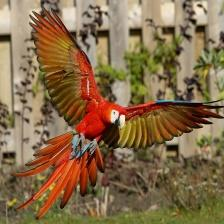

mydir='D:\USER\Desktop\PYTHON CLASS\Bird Classification\Birds\Macaw';
fileformat='*.jpg';
dd=dir(fullfile(mydir,fileformat));
assert(numel(dd) > 0, 'No file was found. Check that the path is correct');
my_img = struct('img', cell(size(dd)));
k=numel(dd)+1;
for zz=1:numel(dd)
my_img(zz).img = imread(fullfile(mydir,dd(zz).name));
end


for i= 1:numel(dd)
    current = imresize(my_img(i).img,[400,400]);
    
%%% Spatial Domain
 % RGB Channels
    % Red image
    RedMean = mean(mean(current(:,:,1))); 
    RedMedian = median(median(current(:,:,1)));
    % Green image
    GreenMean = mean(mean(current(:,:,2))); 
    GreenMedian = median(median(current(:,:,2))); 
    % Blue image
    BlueMean = mean(mean(current(:,:,3))); 
    BlueMedian = median(median(current(:,:,3)));

    % Gray Scale Image
    GrayImage = double(rgb2gray(current));

    % Statistical Measures
    Mean = mean(mean(GrayImage)); 
    Median = median(median(GrayImage));
    Maximum = max(max(GrayImage));
    Minimum = min(min(GrayImage));
    Std_Dev = std(std(double(GrayImage)));
    Kurtosis = real(kurtosis(GrayImage,1,'all'));
    Skewness = real(skewness(GrayImage,1,'all'));
    IQR = iqr(GrayImage,'all');

    % Entropy -> Statistical measure of randomness that can be used to characterize the texture of input image.
    Entropy = entropy(GrayImage); 
    
%%% Frequency Domain
    % Fast-Fourier Transform of Red Channels
    Red_FFT = fft2(current(:,:,1));
    
    FFT_Mean = real(mean(mean(Red_FFT)));
    FFT_Median = real(median(median(Red_FFT)));
    FFT_Maximum = real(max(max(Red_FFT)));
    FFT_Minimum = real(min(min(Red_FFT)));

    % Haar Wavelet Transformation of Red Channels
    Red_Wave = wave(current(:,:,1),'haar',3); 

    Wave_Mean = real(mean(mean(Red_Wave)));
    Wave_Median = real(median(median(Red_Wave)));
    Wave_Maximum = real(max(max(Red_Wave)));
    Wave_Minimum = real(min(min(Red_Wave)));


    % Discrete Cosine Transformation
    DCT_Img = dct2(current(:,:,1)); 
    DCT = DCT_Img(1,1);


    % Selected Column Values
    Column_Names = [RedMean, RedMedian, GreenMean, GreenMedian, BlueMean, BlueMedian, Mean, Median, Maximum, Minimum, Std_Dev, Kurtosis, Skewness, IQR, Entropy, FFT_Mean, FFT_Median, FFT_Maximum, FFT_Minimum, Wave_Mean, Wave_Median, Wave_Maximum, Wave_Minimum, DCT];
    % Writing into Excel Sheets
    writematrix(Column_Names,'D:\USER\Desktop\PYTHON CLASS\Bird Classification\Birds\Class4.csv','WriteMode', 'append');
end

### `Nothern Cardinal (Class 5)`

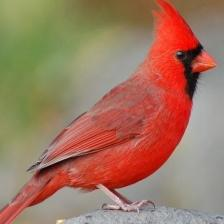

mydir='D:\USER\Desktop\PYTHON CLASS\Bird Classification\Birds\Northern_Cardinal';
fileformat='*.jpg';
dd=dir(fullfile(mydir,fileformat));
assert(numel(dd) > 0, 'No file was found. Check that the path is correct');
my_img = struct('img', cell(size(dd)));
k=numel(dd)+1;
for zz=1:numel(dd)
my_img(zz).img = imread(fullfile(mydir,dd(zz).name));
end


for i= 1:numel(dd)
    current = imresize(my_img(i).img,[400,400]);
    
%%% Spatial Domain
 % RGB Channels
    % Red image
    RedMean = mean(mean(current(:,:,1))); 
    RedMedian = median(median(current(:,:,1)));
    % Green image
    GreenMean = mean(mean(current(:,:,2))); 
    GreenMedian = median(median(current(:,:,2))); 
    % Blue image
    BlueMean = mean(mean(current(:,:,3))); 
    BlueMedian = median(median(current(:,:,3)));

    % Gray Scale Image
    GrayImage = double(rgb2gray(current));

    % Statistical Measures
    Mean = mean(mean(GrayImage)); 
    Median = median(median(GrayImage));
    Maximum = max(max(GrayImage));
    Minimum = min(min(GrayImage));
    Std_Dev = std(std(double(GrayImage)));
    Kurtosis = real(kurtosis(GrayImage,1,'all'));
    Skewness = real(skewness(GrayImage,1,'all'));
    IQR = iqr(GrayImage,'all');

    % Entropy -> Statistical measure of randomness that can be used to characterize the texture of input image.
    Entropy = entropy(GrayImage); 
    
%%% Frequency Domain
    % Fast-Fourier Transform of Red Channels
    Red_FFT = fft2(current(:,:,1));
    
    FFT_Mean = real(mean(mean(Red_FFT)));
    FFT_Median = real(median(median(Red_FFT)));
    FFT_Maximum = real(max(max(Red_FFT)));
    FFT_Minimum = real(min(min(Red_FFT)));

    % Haar Wavelet Transformation of Red Channels
    Red_Wave = wave(current(:,:,1),'haar',3); 

    Wave_Mean = real(mean(mean(Red_Wave)));
    Wave_Median = real(median(median(Red_Wave)));
    Wave_Maximum = real(max(max(Red_Wave)));
    Wave_Minimum = real(min(min(Red_Wave)));


    % Discrete Cosine Transformation
    DCT_Img = dct2(current(:,:,1)); 
    DCT = DCT_Img(1,1);


    % Selected Column Values
    Column_Names = [RedMean, RedMedian, GreenMean, GreenMedian, BlueMean, BlueMedian, Mean, Median, Maximum, Minimum, Std_Dev, Kurtosis, Skewness, IQR, Entropy, FFT_Mean, FFT_Median, FFT_Maximum, FFT_Minimum, Wave_Mean, Wave_Median, Wave_Maximum, Wave_Minimum, DCT];
    % Writing into Excel Sheets
    writematrix(Column_Names,'D:\USER\Desktop\PYTHON CLASS\Bird Classification\Birds\Class5.csv','WriteMode', 'append');
end

### `Parakeets (Class 6)`

### 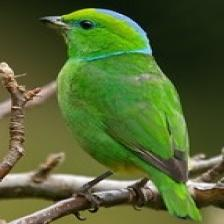

mydir='D:\USER\Desktop\PYTHON CLASS\Bird Classification\Birds\Parakeets';
fileformat='*.jpg';
dd=dir(fullfile(mydir,fileformat));
assert(numel(dd) > 0, 'No file was found. Check that the path is correct');
my_img = struct('img', cell(size(dd)));
k=numel(dd)+1;
for zz=1:numel(dd)
my_img(zz).img = imread(fullfile(mydir,dd(zz).name));
end


for i= 1:numel(dd)
    current = imresize(my_img(i).img,[400,400]);
    
%%% Spatial Domain
 % RGB Channels
    % Red image
    RedMean = mean(mean(current(:,:,1))); 
    RedMedian = median(median(current(:,:,1)));
    % Green image
    GreenMean = mean(mean(current(:,:,2))); 
    GreenMedian = median(median(current(:,:,2))); 
    % Blue image
    BlueMean = mean(mean(current(:,:,3))); 
    BlueMedian = median(median(current(:,:,3)));

    % Gray Scale Image
    GrayImage = double(rgb2gray(current));

    % Statistical Measures
    Mean = mean(mean(GrayImage)); 
    Median = median(median(GrayImage));
    Maximum = max(max(GrayImage));
    Minimum = min(min(GrayImage));
    Std_Dev = std(std(double(GrayImage)));
    Kurtosis = real(kurtosis(GrayImage,1,'all'));
    Skewness = real(skewness(GrayImage,1,'all'));
    IQR = iqr(GrayImage,'all');

    % Entropy -> Statistical measure of randomness that can be used to characterize the texture of input image.
    Entropy = entropy(GrayImage); 
    
%%% Frequency Domain
    % Fast-Fourier Transform of Red Channels
    Red_FFT = fft2(current(:,:,1));
    
    FFT_Mean = real(mean(mean(Red_FFT)));
    FFT_Median = real(median(median(Red_FFT)));
    FFT_Maximum = real(max(max(Red_FFT)));
    FFT_Minimum = real(min(min(Red_FFT)));

    % Haar Wavelet Transformation of Red Channels
    Red_Wave = wave(current(:,:,1),'haar',3); 

    Wave_Mean = real(mean(mean(Red_Wave)));
    Wave_Median = real(median(median(Red_Wave)));
    Wave_Maximum = real(max(max(Red_Wave)));
    Wave_Minimum = real(min(min(Red_Wave)));


    % Discrete Cosine Transformation
    DCT_Img = dct2(current(:,:,1)); 
    DCT = DCT_Img(1,1);



    % Selected Column Values
    Column_Names = [RedMean, RedMedian, GreenMean, GreenMedian, BlueMean, BlueMedian, Mean, Median, Maximum, Minimum, Std_Dev, Kurtosis, Skewness, IQR, Entropy, FFT_Mean, FFT_Median, FFT_Maximum, FFT_Minimum, Wave_Mean, Wave_Median, Wave_Maximum, Wave_Minimum, DCT];
    % Writing into Excel Sheets
    writematrix(Column_Names,'D:\USER\Desktop\PYTHON CLASS\Bird Classification\Birds\Class6.csv','WriteMode', 'append');
end

### `Parrots (Class 7)`

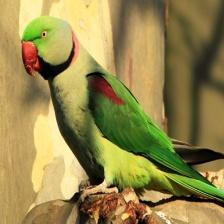

mydir='D:\USER\Desktop\PYTHON CLASS\Bird Classification\Birds\Parrot';
fileformat='*.jpg';
dd=dir(fullfile(mydir,fileformat));
assert(numel(dd) > 0, 'No file was found. Check that the path is correct');
my_img = struct('img', cell(size(dd)));
k=numel(dd)+1;
for zz=1:numel(dd)
my_img(zz).img = imread(fullfile(mydir,dd(zz).name));
end


for i= 1:numel(dd)
    current = imresize(my_img(i).img,[400,400]);
    
%%% Spatial Domain
 % RGB Channels
    % Red image
    RedMean = mean(mean(current(:,:,1))); 
    RedMedian = median(median(current(:,:,1)));
    % Green image
    GreenMean = mean(mean(current(:,:,2))); 
    GreenMedian = median(median(current(:,:,2))); 
    % Blue image
    BlueMean = mean(mean(current(:,:,3))); 
    BlueMedian = median(median(current(:,:,3)));

    % Gray Scale Image
    GrayImage = double(rgb2gray(current));

    % Statistical Measures
    Mean = mean(mean(GrayImage)); 
    Median = median(median(GrayImage));
    Maximum = max(max(GrayImage));
    Minimum = min(min(GrayImage));
    Std_Dev = std(std(double(GrayImage)));
    Kurtosis = real(kurtosis(GrayImage,1,'all'));
    Skewness = real(skewness(GrayImage,1,'all'));
    IQR = iqr(GrayImage,'all');

    % Entropy -> Statistical measure of randomness that can be used to characterize the texture of input image.
    Entropy = entropy(GrayImage); 
    
%%% Frequency Domain
    % Fast-Fourier Transform of Red Channels
    Red_FFT = fft2(current(:,:,1));
    
    FFT_Mean = real(mean(mean(Red_FFT)));
    FFT_Median = real(median(median(Red_FFT)));
    FFT_Maximum = real(max(max(Red_FFT)));
    FFT_Minimum = real(min(min(Red_FFT)));

    % Haar Wavelet Transformation of Red Channels
    Red_Wave = wave(current(:,:,1),'haar',3); 

    Wave_Mean = real(mean(mean(Red_Wave)));
    Wave_Median = real(median(median(Red_Wave)));
    Wave_Maximum = real(max(max(Red_Wave)));
    Wave_Minimum = real(min(min(Red_Wave)));


    % Discrete Cosine Transformation
    DCT_Img = dct2(current(:,:,1)); 
    DCT = DCT_Img(1,1);


    % Selected Column Values
    Column_Names = [RedMean, RedMedian, GreenMean, GreenMedian, BlueMean, BlueMedian, Mean, Median, Maximum, Minimum, Std_Dev, Kurtosis, Skewness, IQR, Entropy, FFT_Mean, FFT_Median, FFT_Maximum, FFT_Minimum, Wave_Mean, Wave_Median, Wave_Maximum, Wave_Minimum, DCT];
    % Writing into Excel Sheets
    writematrix(Column_Names,'D:\USER\Desktop\PYTHON CLASS\Bird Classification\Birds\Class7.csv','WriteMode', 'append');
end

### `Toucans (Class 8)`

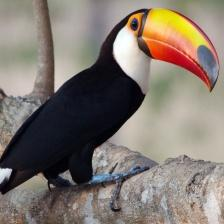

mydir='D:\USER\Desktop\PYTHON CLASS\Bird Classification\Birds\Toucans';
fileformat='*.jpg';
dd=dir(fullfile(mydir,fileformat));
assert(numel(dd) > 0, 'No file was found. Check that the path is correct');
my_img = struct('img', cell(size(dd)));
k=numel(dd)+1;
for zz=1:numel(dd)
my_img(zz).img = imread(fullfile(mydir,dd(zz).name));
end


for i= 1:numel(dd)
    current = imresize(my_img(i).img,[400,400]);
    
%%% Spatial Domain
 % RGB Channels
    % Red image
    RedMean = mean(mean(current(:,:,1))); 
    RedMedian = median(median(current(:,:,1)));
    % Green image
    GreenMean = mean(mean(current(:,:,2))); 
    GreenMedian = median(median(current(:,:,2))); 
    % Blue image
    BlueMean = mean(mean(current(:,:,3))); 
    BlueMedian = median(median(current(:,:,3)));

    % Gray Scale Image
    GrayImage = double(rgb2gray(current));

    % Statistical Measures
    Mean = mean(mean(GrayImage)); 
    Median = median(median(GrayImage));
    Maximum = max(max(GrayImage));
    Minimum = min(min(GrayImage));
    Std_Dev = std(std(double(GrayImage)));
    Kurtosis = real(kurtosis(GrayImage,1,'all'));
    Skewness = real(skewness(GrayImage,1,'all'));
    IQR = iqr(GrayImage,'all');

    % Entropy -> Statistical measure of randomness that can be used to characterize the texture of input image.
    Entropy = entropy(GrayImage); 
    
%%% Frequency Domain
    % Fast-Fourier Transform of Red Channels
    Red_FFT = fft2(current(:,:,1));
    
    FFT_Mean = real(mean(mean(Red_FFT)));
    FFT_Median = real(median(median(Red_FFT)));
    FFT_Maximum = real(max(max(Red_FFT)));
    FFT_Minimum = real(min(min(Red_FFT)));

    % Haar Wavelet Transformation of Red Channels
    Red_Wave = wave(current(:,:,1),'haar',3); 

    Wave_Mean = real(mean(mean(Red_Wave)));
    Wave_Median = real(median(median(Red_Wave)));
    Wave_Maximum = real(max(max(Red_Wave)));
    Wave_Minimum = real(min(min(Red_Wave)));


    % Discrete Cosine Transformation
    DCT_Img = dct2(current(:,:,1)); 
    DCT = DCT_Img(1,1);

    % Selected Column Values
    Column_Names = [RedMean, RedMedian, GreenMean, GreenMedian, BlueMean, BlueMedian, Mean, Median, Maximum, Minimum, Std_Dev, Kurtosis, Skewness, IQR, Entropy, FFT_Mean, FFT_Median, FFT_Maximum, FFT_Minimum, Wave_Mean, Wave_Median, Wave_Maximum, Wave_Minimum, DCT];
    % Writing into Excel Sheets
    writematrix(Column_Names,'D:\USER\Desktop\PYTHON CLASS\Bird Classification\Birds\Class8.csv','WriteMode', 'append');
end

## Function to get the Wavelet Transformation

function A3 = wave(im, wname, no_levels)
    [C, S]=wavedec2(im2double(im),no_levels,wname);
    A3=appcoef2(C,S,wname,no_levels);
end